# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.5 三维曲线、散点图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

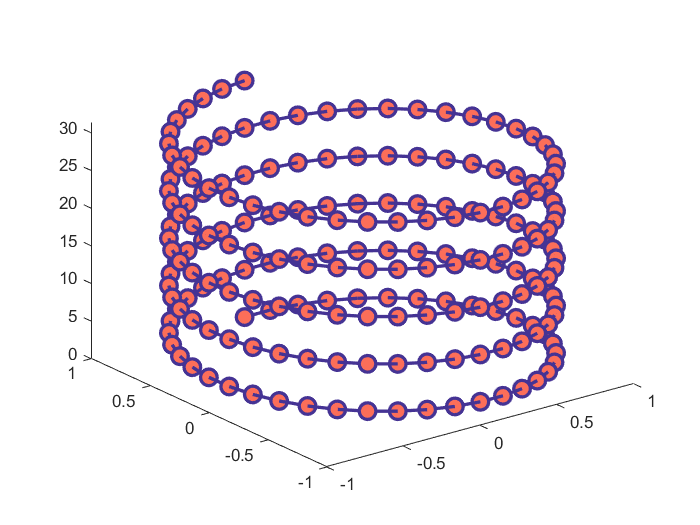

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();  
%%%%% 三维曲线图
figure;
t = 0:pi/20:10*pi;
xt = sin(t);
yt = cos(t);
plot3(xt, yt, t, '-o', 'Color', all_colors(6, :), 'MarkerSize', 10, ...
    'MarkerFaceColor', all_colors(1, :), 'LineWidth', 2);

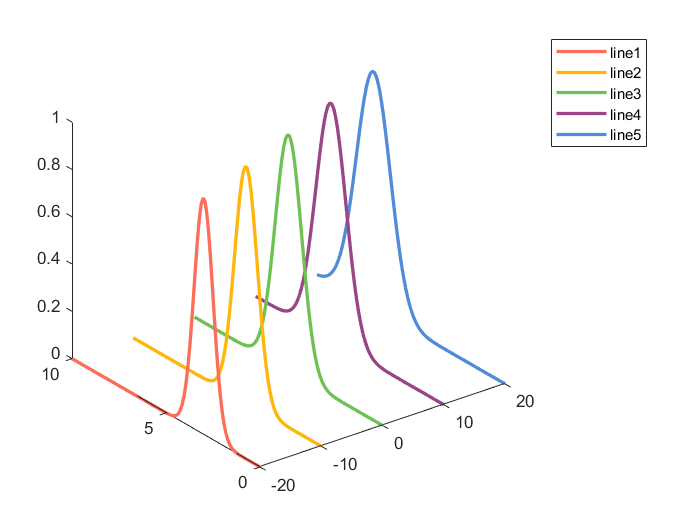

figure;
x = -20:10:20;
y = linspace(0, 10, 100);
% 生成 5 组数据
z = zeros(5, 100);
z(1, :) = gaussmf(y, [0.5 3]);
z(2, :) = gaussmf(y, [0.6 4]);
z(3, :) = gaussmf(y, [0.7 5]);
z(4, :) = gaussmf(y, [0.8 6]);
z(5, :) = gaussmf(y, [0.9 7]);
for i = 1:5
    % x 方向每条曲线都是一个值
    xx = x(i)*ones(1, 100);
    % z 方向的值，每次取一条
    zz = z(i, :);
    % plot3 在 xyz 空间绘制曲线，保证 x y z 长度一致即可
    plot3(xx, y, zz, 'LineWidth', 2);
    hold on
end
hold off
% 定制颜色
set(gca, 'colororder', all_themes{1});
legend('line1', 'line2', 'line3', 'line4', 'line5');

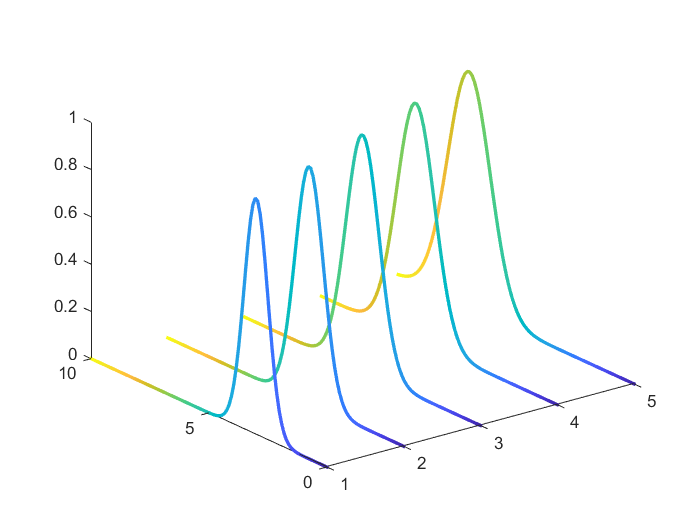

% 如果把渐变曲线和三维曲线结合起来
figure;
x = linspace(0, 10, 100);
y = zeros(5, 100);
y(1, :) = gaussmf(x, [0.5 3]);
y(2, :) = gaussmf(x, [0.6 4]);
y(3, :) = gaussmf(x, [0.7 5]);
y(4, :) = gaussmf(x, [0.8 6]);
y(5, :) = gaussmf(x, [0.9 7]);
for i = 1:5
    fill3([i*ones(size(x)), NaN], [x, NaN], [y(i, :), NaN], [x NaN], 'EdgeColor', 'interp', 'LineWidth', 2)
    hold on
end
hold off

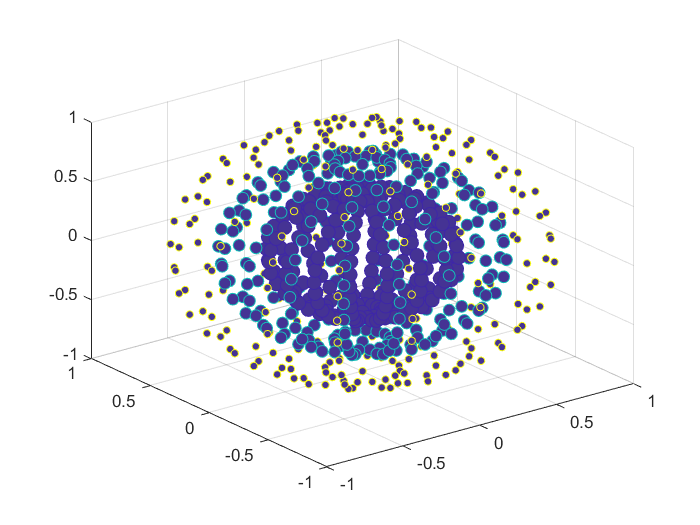

%%%%% 三维散点图
figure;
[X,Y,Z] = sphere(16);
x = [0.5*X(:); 0.75*X(:); X(:)];
y = [0.5*Y(:); 0.75*Y(:); Y(:)];
z = [0.5*Z(:); 0.75*Z(:); Z(:)];
S = repmat([70, 50, 20],numel(X), 1);
C = repmat([1, 2, 3], numel(X), 1);
s = S(:);
c = C(:);
h = scatter3(x, y, z, s, c);
h.MarkerFaceColor = all_colors(6, :);

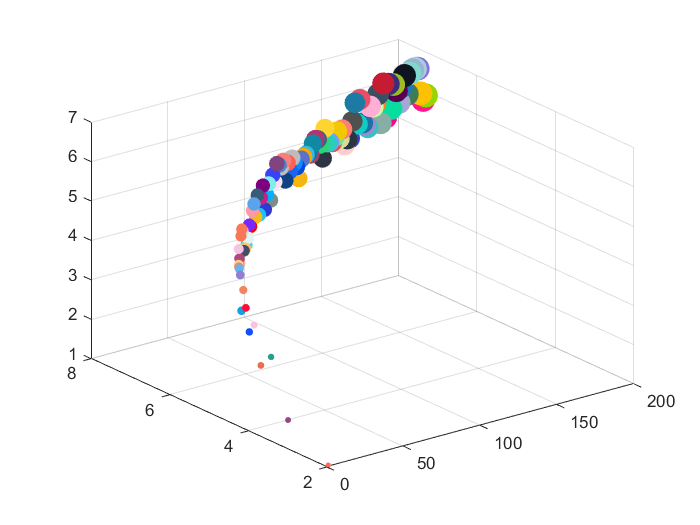

figure;
x = linspace(1, 200, 100);
y1 = log(x) + 1;
y2 = log(x) + 2;
y3 = y1 + rand(1, 100) - 0.5;
figure;
scatter3(x, y2, y3, x + 10, x, 'filled');
% 定制颜色
colormap(all_colors);